#  vcProject 3

This project is completed by Group3, with code reference to inv_soln5, call_Ex_22_19_6.mlx, optexp_Fig8_10 and CI_bootstrap3.

## 0. Preprocessing

clear % Clear the workspace.
close all; % Close all figures.
format compact
format short

## 1. Read in Data and Initial parameters

global nS

Set1   = 1;
data1  = load( '0.15LogN-t.mat' );    %readin data
x1     = data1.Data001(:,1);         %first column
yobs1  = data1.Data001(:,2);         %second column
nL(1)  = length(x1);

Set2   = 2;
data2  = load( '0.40LogN-t.mat' );    %readin data
x2     = data2.Data002(:,1);         %first column
yobs2  = data2.Data002(:,2);         %second column
nL(2)  = length(x2);

Set3   = 3;
data3  = load( '1.64LogN-t.mat' );    %readin data
x3     = data3.Data001(:,1);         %first column
yobs3  = data3.Data001(:,2);         %second column
nL(3)  = length(x3);

nS      = cumsum(nL)

nS =     23    43    60


xobs   = [x1; x2; x3]

xobs =     0.0979
   17.3638
   34.9001
   52.9780
   71.0644
   88.8719
  106.9674
  125.3186
  143.4000
  165.3121


yobs   = [yobs1; yobs2; yobs3]

yobs =     9.5055
    9.4136
    9.3795
    9.4497
    9.3809
    9.3932
    9.1741
    9.2558
    9.2681
    9.3614


%beta0(1)=AsymD, beta0(2)=z, beta0(3)=logCc0=constant 0.82
beta0(1)   = 5.67;
beta0(2)   = 4.11;
%beta0(3)   = 0.82;

logCc0     =0.82;
ln10    = 2.3026;
Tref    = 56.3;
Tdiff   = 25;
T0      = 30;
B       = 5*10^-4;
Y0      = [9.49; 9.26; 9.42];
Tcrit   = [168.27; 61.98; 15.27];

## 2. Initial parameters for ypred and X'

### 2.1 plot ypred with initial parameter guesses on data

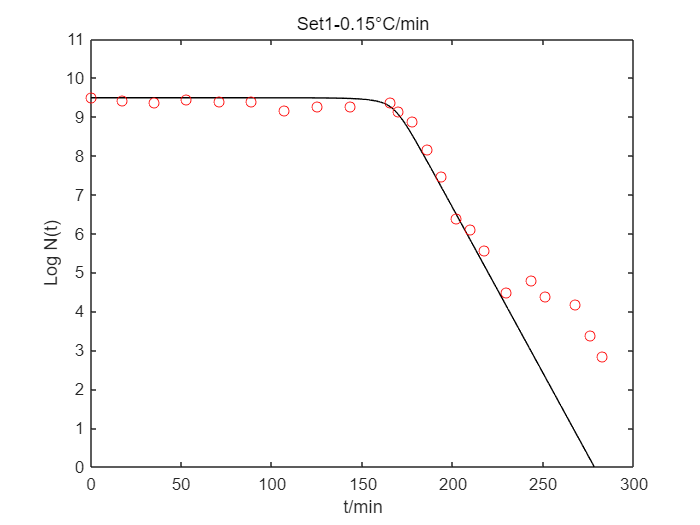

%Initial Guess
fnameFOR = @MicroInactFOR;
%data set1
xs=min(x1):0.01:max(x1);
Set = Set1;
ns=length(xs);
xs = xs';
ypredInit=fnameFOR(beta0, xs, Set);
plot(xs,ypredInit,'-k',x1,yobs1,'or');
title('Set1-0.15{\circ}C/min');
xlabel('t/min');
ylabel('Log N(t)');
ylim([0, 11]);
hold off

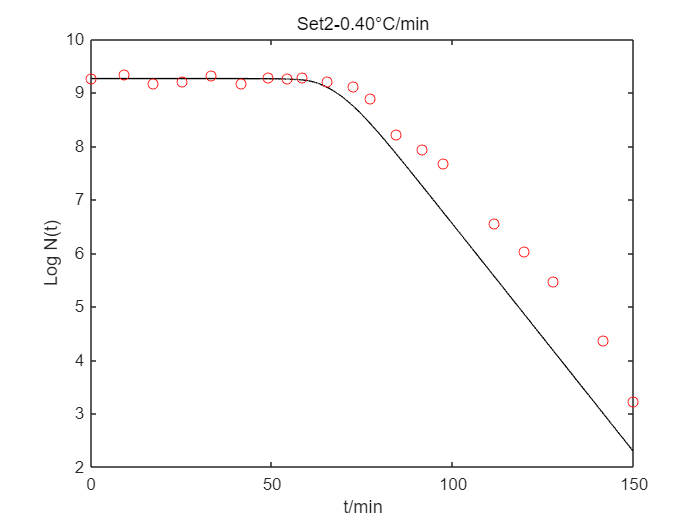

%data set2
xs=min(x2):0.01:max(x2);
Set = Set2;
ns=length(xs);
xs = xs';
ypredInit=fnameFOR(beta0, xs, Set);
plot(xs,ypredInit,'-k',x2,yobs2,'or');
title('Set2-0.40{\circ}C/min');
xlabel('t/min');
ylabel('Log N(t)');
hold off

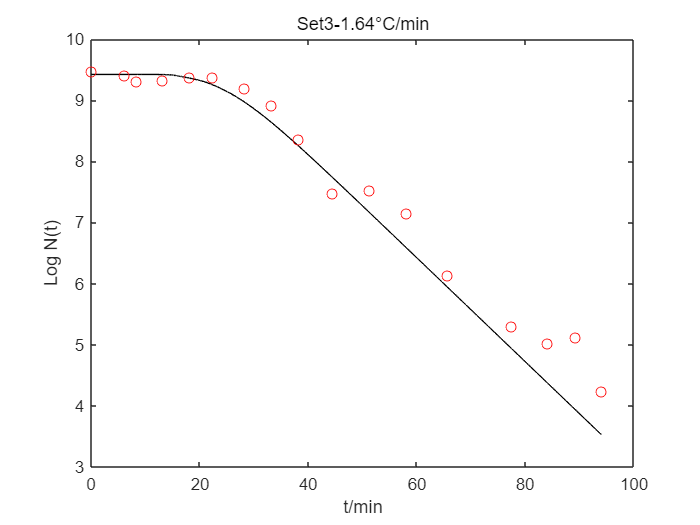

%data set3
xs=min(x3):0.01:max(x3);
Set = Set3;
ns=length(xs);
xs = xs';
ypredInit=fnameFOR(beta0, xs, Set);
plot(xs,ypredInit,'-k',x3,yobs3,'or');
title('Set3-1.64{\circ}C/min');
xlabel('t/min');
ylabel('Log N(t)');
hold off

## 2. Initial parameters for ypred and X'

### 2.2 X' = scaled sensitivity coefficients using forward-difference

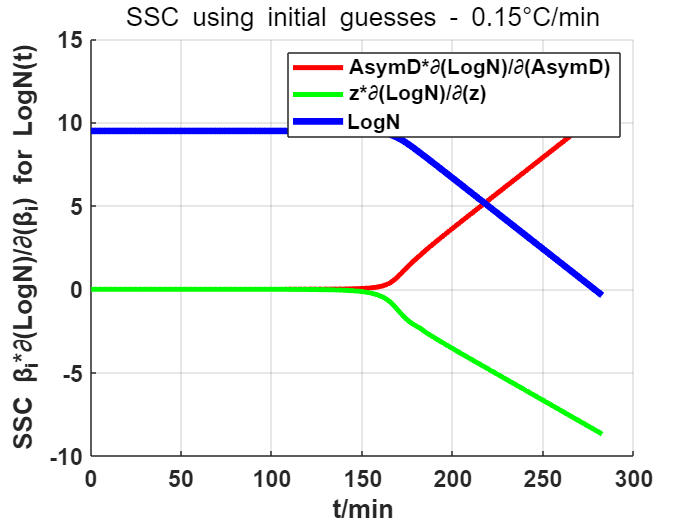

%data set1
Set = Set1;
xs=min(x1):0.01:max(x1);
xs=xs';
ns=length(xs);
Xp=SSC_V3(beta0,xs,fnameFOR,Set);
p=length(beta0);
%% plot X' for each dependent variable
%plot for Y
cmap = ['r' 'g' 'b' 'c' 'y'  'm' 'k' ]'; %color map
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
for i=1:p
    h1(i) = plot(xs(1:ns),Xp(1:ns,i),'-','color',cmap(i,:),'LineWidth',3);
end
%plot y vs t to know the total span
ypred=fnameFOR(beta0,xs,Set);
h1(i+1)=plot(xs,ypred,'-','color',cmap(i+1,:),'LineWidth',4);
legend('AsymD*\partial(LogN)/\partial(AsymD)','z*\partial(LogN)/\partial(z)','LogN')
xlabel('t/min'); ylabel('SSC \beta_i*\partial(LogN)/\partial(\beta_i) for LogN(t)');
title('SSC using initial guesses - 0.15{\circ}C/min')
grid on

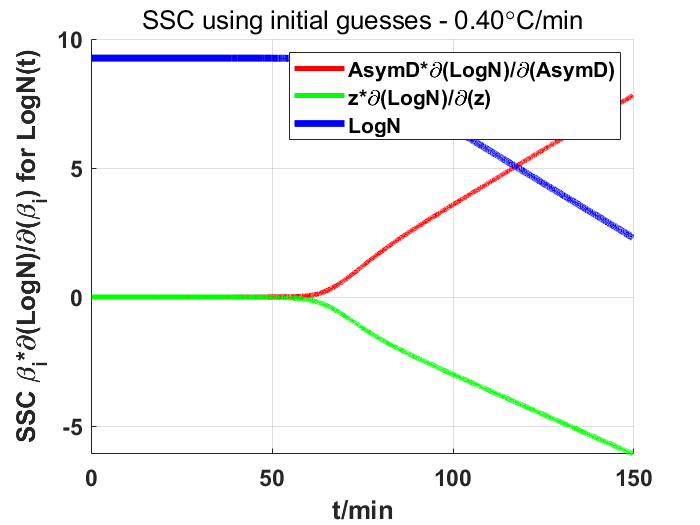

%data set2
Set = Set2;
xs=min(x2):0.01:max(x2);
xs=xs';
ns=length(xs);
Xp=SSC_V3(beta0,xs,fnameFOR,Set);
p=length(beta0);
%% plot X' for each dependent variable
%plot for Y
cmap = ['r' 'g' 'b' 'c' 'y'  'm' 'k' ]'; %color map
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
for i=1:p
    h2(i) = plot(xs(1:ns),Xp(1:ns,i),'-','color',cmap(i,:),'LineWidth',3);
end
%plot y vs t to know the total span
ypred=fnameFOR(beta0,xs,Set);
h2(i+1)=plot(xs,ypred,'-','color',cmap(i+1,:),'LineWidth',4);
legend('AsymD*\partial(LogN)/\partial(AsymD)','z*\partial(LogN)/\partial(z)','LogN')
xlabel('t/min'); ylabel('SSC \beta_i*\partial(LogN)/\partial(\beta_i) for LogN(t)');
title('SSC using initial guesses - 0.40{\circ}C/min')
grid on

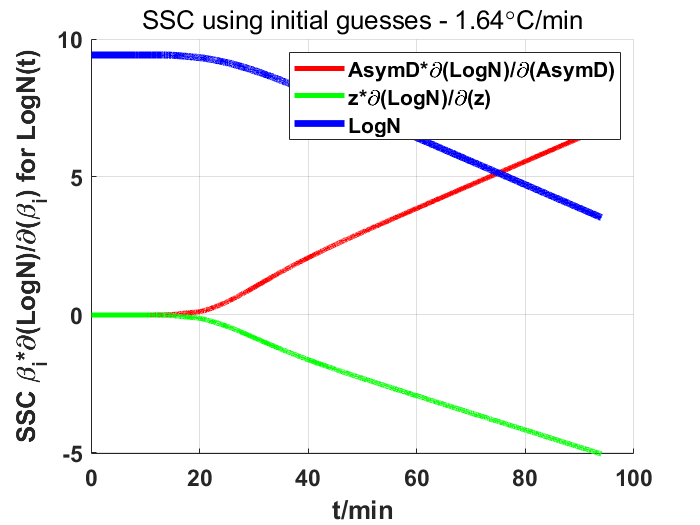

%data set=3
Set = Set3;
xs=min(x3):0.01:max(x3);
xs=xs';
ns=length(xs);
Xp=SSC_V3(beta0,xs,fnameFOR,Set);
p=length(beta0);
%% plot X' for each dependent variable
%plot for Y
cmap = ['r' 'g' 'b' 'c' 'y'  'm' 'k' ]'; %color map
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
for i=1:p
    h3(i) = plot(xs(1:ns),Xp(1:ns,i),'-','color',cmap(i,:),'LineWidth',3);
end
%plot y vs t to know the total span
ypred=fnameFOR(beta0,xs,Set);
h3(i+1)=plot(xs,ypred,'-','color',cmap(i+1,:),'LineWidth',4);
legend('AsymD*\partial(LogN)/\partial(AsymD)','z*\partial(LogN)/\partial(z)','LogN')
xlabel('t/min'); ylabel('SSC \beta_i*\partial(LogN)/\partial(\beta_i) for LogN(t)');
title('SSC using initial guesses - 1.64{\circ}C/min')
grid on

## 3. Estimate parameters using inverse problem with nlinfit

### 3.1 nlinfit returns parameters

fnameINV=@MicroInactINV;

[beta,resids,J,COVB,mse] = nlinfit(xobs,yobs,fnameINV,beta0);
beta %parameter estimates

beta =     6.7255    3.8104


AsymD=beta(1)

AsymD = 6.7255

z=beta(2)

z = 3.8104

## 3. Estimate parameters using inverse problem with nlinfit

### 3.2 residuals, Jacobian and confidence intervals for parameters

ss=resids'*resids; %sum of squares
p=length(beta); % number of parameters
rmse=sqrt(mse)  %root mean square error

rmse = 0.4274

meanres = mean(resids)

meanres = -0.0849

condX=cond(J)%needs to be < 10^6.  J is the sensitivity matrix = X

condX = 33.8878

detXTX=det(J'*J) %needs to be far from zero

detXTX = 1.6531

ci=nlparci(beta, resids,J)

ci =     3.0521   10.3990
    1.3986    6.2223


[R,sigma]=corrcov(COVB);
R

R =     1.0000    0.9979
    0.9979    1.0000


sigma  %standard errors

sigma =     1.8352
    1.2049


relerr=sigma./beta' %relative error (coefficient of variance) for each parameter

relerr =     0.2729
    0.3162


%Confidence and prediction intervals for the dependent variable
[ypred, delta] = nlpredci(fnameINV,xobs,beta,resids,J,0.05,'on','curve'); %confidence band for regression line
[ypred, deltaob] =nlpredci(fnameINV,xobs,beta,resids,J,0.05,'on','observation');%prediction band for individual points

yspan=range(ypred);% total span of ypred
relrmse=rmse/yspan % ratio of rmse vs. yspan

relrmse = 0.0557

%simultaneous confidence bands for regression line
CBu=ypred+delta;
CBl=ypred-delta;
%simultaneous prediction bands for individual points
PBu=ypred+deltaob;
PBl=ypred-deltaob;

## 4. Outputs

### 4.1 Outputs of Data Set1: X', CIs and PIs, Residuals

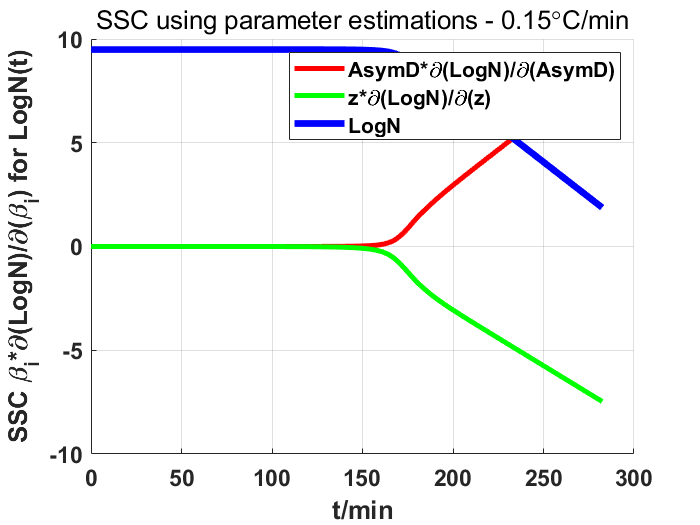

%data set1
Set = Set1;

xs=min(x1):0.01:max(x1);
xs=xs';
ns=length(xs);
Xp=SSC_V3(beta,xs,fnameFOR,Set);
p=length(beta);
%% plot X' for each dependent variable
%plot for Y
cmap = ['r' 'g' 'b' 'c' 'y'  'm' 'k' ]'; %color map
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
for i=1:p
    h1(i) = plot(xs(1:ns),Xp(1:ns,i),'-','color',cmap(i,:),'LineWidth',3);
end
%plot y vs t to know the total span
ypred1=fnameFOR(beta,xs,Set);
h1(i+1)=plot(xs,ypred1,'-','color',cmap(i+1,:),'LineWidth',4);
legend('AsymD*\partial(LogN)/\partial(AsymD)','z*\partial(LogN)/\partial(z)','LogN')
xlabel('t/min'); ylabel('SSC \beta_i*\partial(LogN)/\partial(\beta_i) for LogN(t)');
title('SSC using parameter estimations - 0.15{\circ}C/min')
grid on
hold off

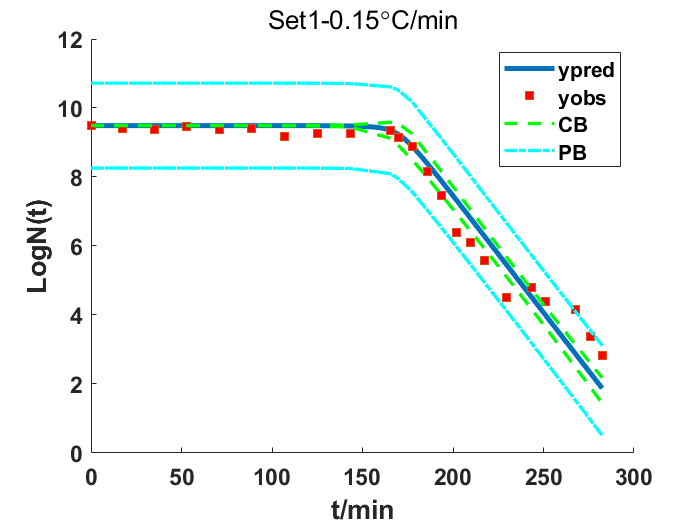

%data set1
xs=min(x1):0.01:max(x1);
Set = Set1;
ns=length(xs);
xs = xs';

%Output--ypred and yobs vs. t
figure 
hold on
ypredp=fnameFOR(beta,xs,Set);%ypredp for plotting
set(gca, 'fontsize',14,'fontweight','bold');
h1(1)=plot(xs,ypredp,'-','linewidth',3); %predicted y values
h1(2)=plot(x1,yobs1,'square', 'Markerfacecolor', 'r');
xlabel('t/min','fontsize',16,'fontweight','bold')
ylabel('LogN(t)','fontsize',16,'fontweight','bold')

%Output --CIs and PIs
%plot Yobs, Ypred line, confidence band for regression line
h1(3) = plot(x1,CBu(1:nS(1)),'--g','LineWidth',2);
plot(x1,CBl(1:nS(1)),'--g','LineWidth',2);
%plot prediction band for regression line
h1(4) = plot(x1,PBu(1:nS(1)),'-.c','LineWidth',2);
plot(x1,PBl(1:nS(1)),'-.c','LineWidth',2);
title('Set1-0.15{\circ}C/min');
legend(h1,'ypred','yobs','CB','PB')

% residual scatter plot
figure
hold on
plot(x1, resids(1:nS(1)), 'square','Markerfacecolor', 'b');
YLine = [0 0]; 
XLine = [0 max(x1)];
plot (XLine, YLine,'R'); %plot a straight red line at zero
ylabel('yobs - ypred','fontsize',16,'fontweight','bold')
xlabel('t/min','fontsize',16,'fontweight','bold')
grid on
set(gca, 'fontsize',14,'fontweight','bold');
title('Set1-0.15{\circ}C/min');
meanres=mean(resids(1:nS(1)))

meanres = -0.0264

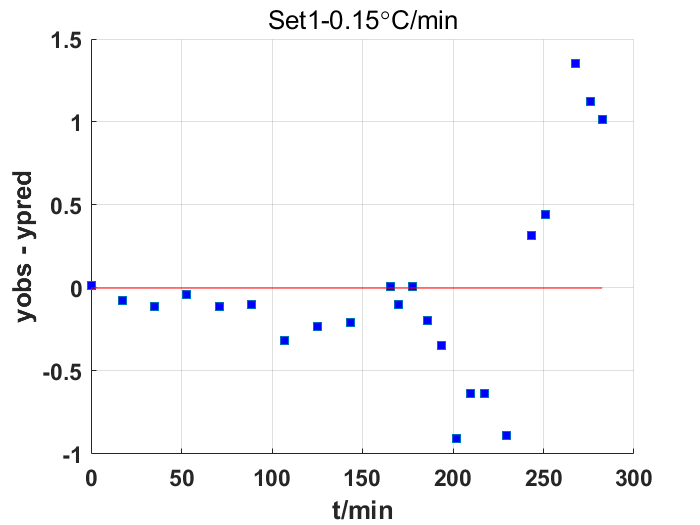

hold off

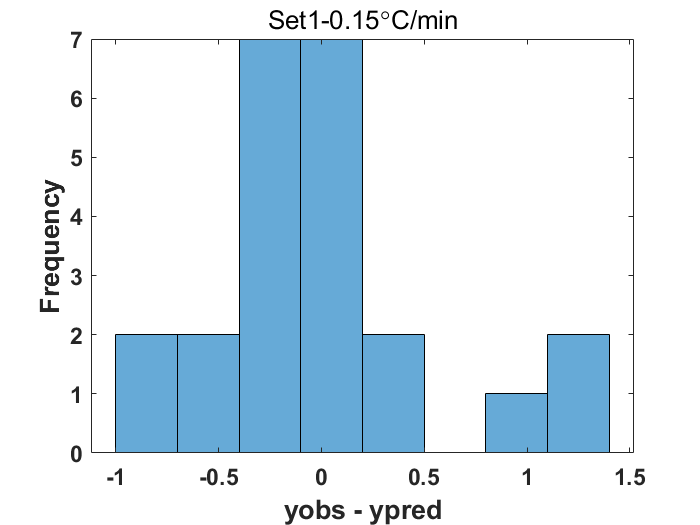

% residuals histogram
 figure
 h=histogram(resids(1:nS(1)), 'NumBins', 8);
 hold on
 set(gca, 'fontsize',14,'fontweight','bold');
 title('Set1-0.15{\circ}C/min');
 xlabel('yobs - ypred','fontsize',16,'fontweight','bold')
 ylabel('Frequency','fontsize',16,'fontweight','bold')

 %number of runs = number of times moving from one residual to the next crosses zero
    rescross=resids(2:nS(1)).*resids(1:nS(1)-1);%multiply each pair of residuals
    res_sign=sign(rescross);%get the sign of each multiplied pair
    count=0;
    for i=1:nL(1)-1
        if res_sign(i)<0 %if product of pair is < 0, that's a run
            count=count+1;
        end
    end
    fprintf('number of runs = %5.2f\n',count);

number of runs =  6.00


    minrun=(nL(1)+1)/2; %count should be >=minrun
    fprintf('Minimum required number of runs = %5.2f\n',minrun);

Minimum required number of runs = 12.00


## 4. Outputs

### 4.2 Outputs of Data Set2: X', CIs and PIs, Residuals

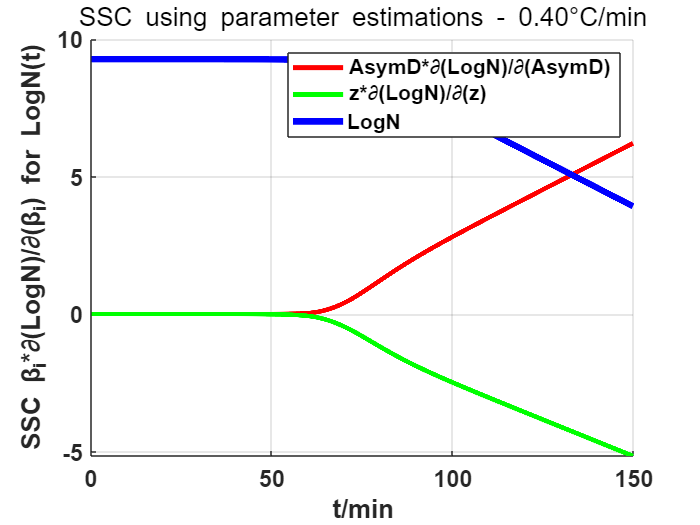

% data set2
Set = Set2;

xs=min(x2):0.01:max(x2);
xs=xs';
ns=length(xs);
Xp=SSC_V3(beta,xs,fnameFOR,Set);
p=length(beta);
%% plot X' for each dependent variable
%plot for Y
cmap = ['r' 'g' 'b' 'c' 'y'  'm' 'k' ]'; %color map
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
for i=1:p
    h1(i) = plot(xs(1:ns),Xp(1:ns,i),'-','color',cmap(i,:),'LineWidth',3);
end
%plot y vs t to know the total span
ypred2=fnameFOR(beta,xs,Set);
h1(i+1)=plot(xs,ypred2,'-','color',cmap(i+1,:),'LineWidth',4);
legend('AsymD*\partial(LogN)/\partial(AsymD)','z*\partial(LogN)/\partial(z)','LogN')
xlabel('t/min'); ylabel('SSC \beta_i*\partial(LogN)/\partial(\beta_i) for LogN(t)');
title('SSC using parameter estimations - 0.40{\circ}C/min')
grid on
hold off

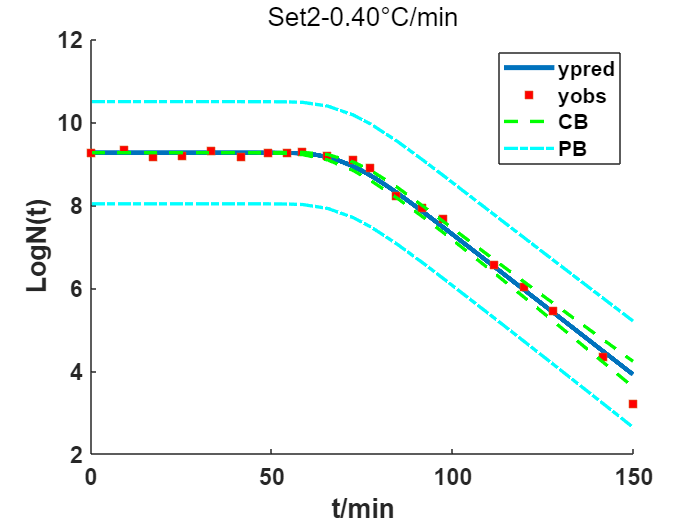

% data set2
xs=min(x2):0.01:max(x2);
Set = Set2;
ns=length(xs);
xs = xs';

%Output--ypred and yobs vs. t
figure 
hold on
ypredp=fnameFOR(beta,xs,Set);%ypredp for plotting
set(gca, 'fontsize',14,'fontweight','bold');
h1(1)=plot(xs,ypredp,'-','linewidth',3); %predicted y values
h1(2)=plot(x2,yobs2,'square', 'Markerfacecolor', 'r');
xlabel('t/min','fontsize',16,'fontweight','bold')
ylabel('LogN(t)','fontsize',16,'fontweight','bold')

%Output --CIs and PIs
%plot Yobs, Ypred line, confidence band for regression line
h1(3) = plot(x2,CBu(nS(1)+1:nS(2)),'--g','LineWidth',2);
plot(x2,CBl(nS(1)+1:nS(2)),'--g','LineWidth',2);
%plot prediction band for regression line
h1(4) = plot(x2,PBu(nS(1)+1:nS(2)),'-.c','LineWidth',2);
plot(x2,PBl(nS(1)+1:nS(2)),'-.c','LineWidth',2);
title('Set2-0.40{\circ}C/min');
legend(h1,'ypred','yobs','CB','PB')

% residual scatter plot
figure
hold on
plot(x2, resids(nS(1)+1:nS(2)), 'square','Markerfacecolor', 'b');
YLine = [0 0]; 
XLine = [0 max(x2)];
plot (XLine, YLine,'R'); %plot a straight red line at zero
ylabel('yobs - ypred','fontsize',16,'fontweight','bold')
xlabel('t/min','fontsize',16,'fontweight','bold')
grid on
set(gca, 'fontsize',14,'fontweight','bold');
title('Set2-0.40{\circ}C/min');
meanres=mean(resids(nS(1)+1:nS(2)))

meanres = -0.0047

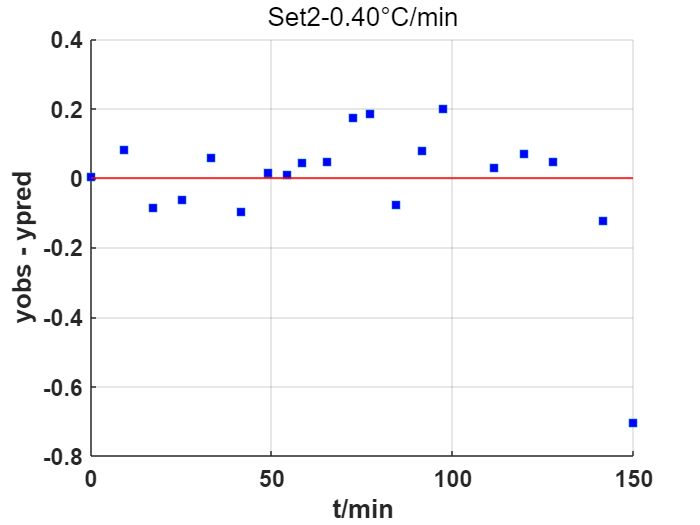

hold off

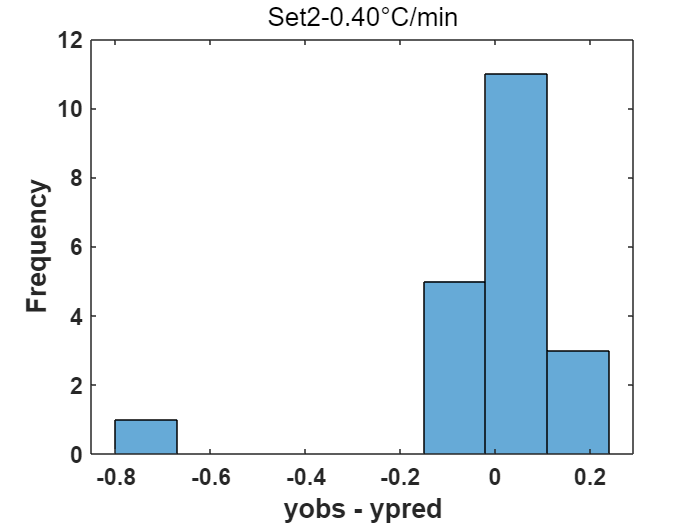


% residuals histogram
 figure
 h=histogram(resids(nS(1)+1:nS(2)), 'NumBins', 8);
 hold on
 set(gca, 'fontsize',14,'fontweight','bold');
 title('Set2-0.40{\circ}C/min');
 xlabel('yobs - ypred','fontsize',16,'fontweight','bold')
 ylabel('Frequency','fontsize',16,'fontweight','bold')

 %number of runs = number of times moving from one residual to the next crosses zero
    rescross=resids(nS(1)+2:nS(2)).*resids(nS(1)+1:nS(2)-1);%multiply each pair of residuals
    res_sign=sign(rescross);%get the sign of each multiplied pair
    count=0;
    for i=1:nL(2)-1
        if res_sign(i)<0 %if product of pair is < 0, that's a run
            count=count+1;
        end
    end
    fprintf('number of runs = %5.2f\n',count);

number of runs =  7.00


    minrun=(nL(2)+1)/2; %count should be >=minrun
    fprintf('Minimum required number of runs = %5.2f\n',minrun);

Minimum required number of runs = 10.50


## 4. Outputs

### 4.3 Outputs of Data Set3: X', CIs and PIs, Residuals

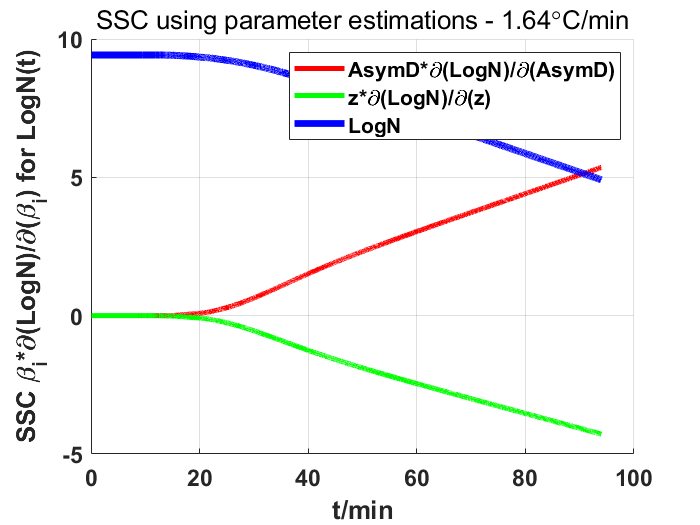

% data set3
Set = Set3;
xs=min(x3):0.01:max(x3);
xs=xs';
ns=length(xs);
Xp=SSC_V3(beta,xs,fnameFOR,Set);
p=length(beta);
%% plot X' for each dependent variable
%plot for Y
cmap = ['r' 'g' 'b' 'c' 'y'  'm' 'k' ]'; %color map
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
for i=1:p
    h1(i) = plot(xs(1:ns),Xp(1:ns,i),'-','color',cmap(i,:),'LineWidth',3);
end
%plot y vs t to know the total span
ypred3=fnameFOR(beta,xs,Set);
h1(i+1)=plot(xs,ypred3,'-','color',cmap(i+1,:),'LineWidth',4);
legend('AsymD*\partial(LogN)/\partial(AsymD)','z*\partial(LogN)/\partial(z)','LogN')
xlabel('t/min'); ylabel('SSC \beta_i*\partial(LogN)/\partial(\beta_i) for LogN(t)');
title('SSC using parameter estimations - 1.64{\circ}C/min')
grid on
hold off

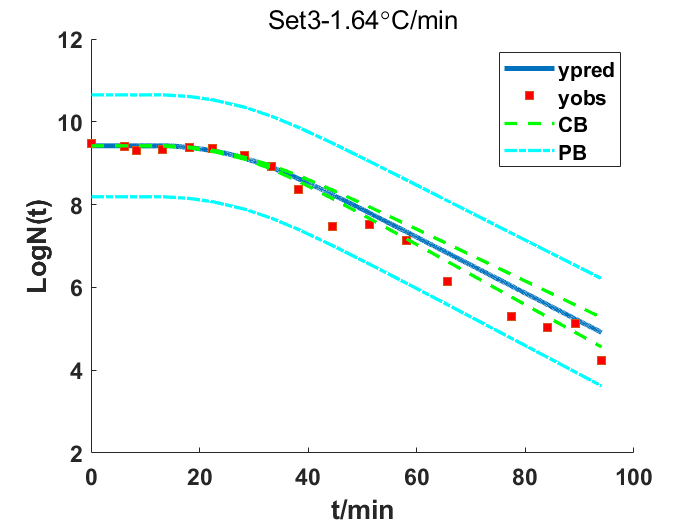

% data set3
xs=min(x3):0.01:max(x3);
Set = Set3;
ns=length(xs);
xs = xs';

%Output--ypred and yobs vs. t
figure 
hold on
ypredp=fnameFOR(beta,xs,Set);%ypredp for plotting
set(gca, 'fontsize',14,'fontweight','bold');
h1(1)=plot(xs,ypredp,'-','linewidth',3); %predicted y values
h1(2)=plot(x3,yobs3,'square', 'Markerfacecolor', 'r');
xlabel('t/min','fontsize',16,'fontweight','bold')
ylabel('LogN(t)','fontsize',16,'fontweight','bold')

%Output --CIs and PIs
%plot Yobs, Ypred line, confidence band for regression line
h1(3) = plot(x3,CBu(nS(2)+1:nS(3)),'--g','LineWidth',2);
plot(x3,CBl(nS(2)+1:nS(3)),'--g','LineWidth',2);
%plot prediction band for regression line
h1(4) = plot(x3,PBu(nS(2)+1:nS(3)),'-.c','LineWidth',2);
plot(x3,PBl(nS(2)+1:nS(3)),'-.c','LineWidth',2);
title('Set3-1.64{\circ}C/min');
legend(h1,'ypred','yobs','CB','PB')


% residual scatter plot
figure
hold on
plot(x3, resids(nS(2)+1:nS(3)), 'square','Markerfacecolor', 'b');
YLine = [0 0]; 
XLine = [0 max(x3)];
plot (XLine, YLine,'R'); %plot a straight red line at zero
ylabel('yobs - ypred','fontsize',16,'fontweight','bold')
xlabel('t/min','fontsize',16,'fontweight','bold')
grid on
set(gca, 'fontsize',14,'fontweight','bold');
title('Set3-1.64{\circ}C/min');
meanres=mean(resids(nS(2)+1:nS(3)))

meanres = -0.2583

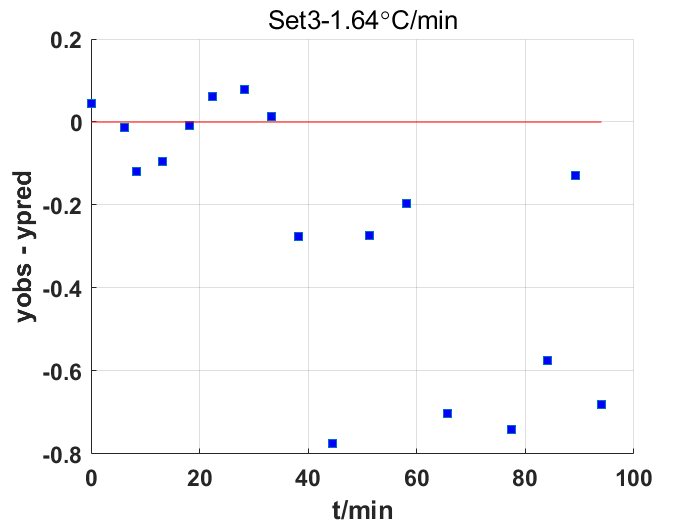

hold off

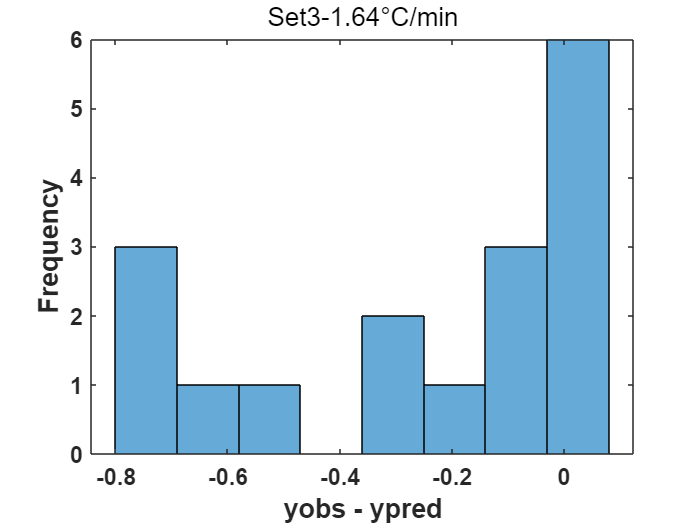


% residuals histogram
 figure
 h=histogram(resids(nS(2)+1:nS(3)), 'NumBins', 8);
 hold on
 set(gca, 'fontsize',14,'fontweight','bold');
 title('Set3-1.64{\circ}C/min');
 xlabel('yobs - ypred','fontsize',16,'fontweight','bold')
 ylabel('Frequency','fontsize',16,'fontweight','bold')

 %number of runs = number of times moving from one residual to the next crosses zero
    rescross=resids((nS(2)+2:nS(3))).*resids(nS(2)+1:nS(3)-1);%multiply each pair of residuals
    res_sign=sign(rescross);%get the sign of each multiplied pair
    count=0;
    for i=1:nL(3)-1
        if res_sign(i)<0 %if product of pair is < 0, that's a run
            count=count+1;
        end
    end
    fprintf('number of runs = %5.2f\n',count);

number of runs =  3.00


    minrun=(nL(3)+1)/2; %count should be >=minrun
    fprintf('Minimum required number of runs = %5.2f\n',minrun);

Minimum required number of runs =  9.00


## 5. Optimal experimental design

### 5.1 Optimal experimental design for Data Set1 - 0.15

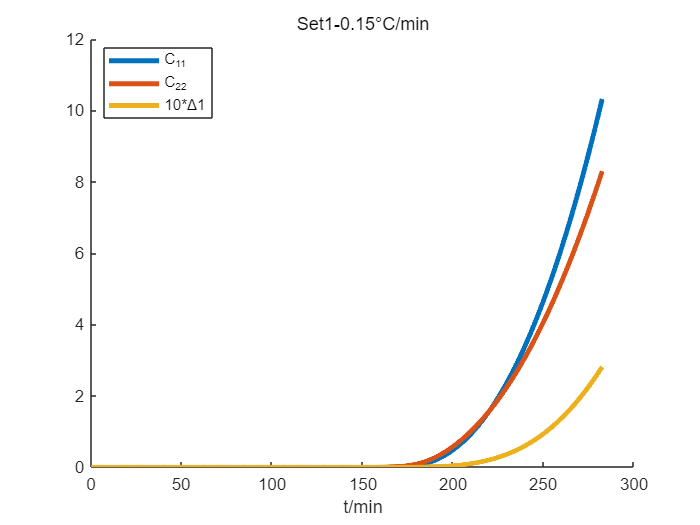

Set = Set1;
%set up times and parameter estimations
t=min(x1):0.1:max(x1);%time
t=t';%make t a column
m=length(t);

beta(1)=AsymD;
beta(2)=z;
p = length(beta);

%% Compute C11, C12,...delta for opt exptl design
fname=@MicroInactFOR;
Xp=SSC_V4(beta,t,fname,Set);%compute scaled sensitivity coefficients as a cell array

%compute entire C matrix
for i=1:p 
    for j=1:p
        intgrnd=Xp{i}.*Xp{j};
        C{i,j}=(1./t).*cumtrapz(t,intgrnd);
        clear intgrnd
    end
end
%to compute delta, must set up the C matrix for each time
for i=1:p
    for j=1:p
        CC1(i,j,:)=C{i,j}; %gives a 3D matrix that is m (depth) in time
    end
end

%set all CC(:,:,1) (first page) values to the appropriate number
CC1(:,:,1)=0;%beginning values at time = 0
CC1(1,1,1)=0;%except for C11, for the initial value
delta1(1)=0; %determinant at time zero.
for k=2:m
    delta1(k)=det(CC1(:,:,k));
end

%convert 3D to 2D for plotting
i=1;
d=1;
%for first row, i =1
for j=1:p
    Cp1(d,:)=CC1(i,j,:); %copies the Cij values for all times and stores in Cp(d,:)
    d=d+1;
end
%for second row, i=2; Cp(3) holds C21
i=2;
for j=2:p
    Cp1(d,:)=CC1(i,j,:);
    d=d+1;
end


figure
hold on
fac=32;%factor for plotting
f=1;%factor
h(1)=plot(t,Cp1(1,:),'-','linewidth',3);%C11
h(2)=plot(t,f*Cp1(3,:),'-','linewidth',3);%C22
h(3)=plot(t,10*f*delta1,'-','linewidth',3);
%set(gca,'YTick',0:.2:1.6)
%set(gca, 'fontsize',28,'fontweight','bold');
ylim([0, 12]);
xlabel('t/min')
title('Set1-0.15{\circ}C/min');
legend('C_{11}','C_{22}','10*\Delta1','Location','Best')

### 5.2 Optimal experimental design for Data Set2 - 0.40

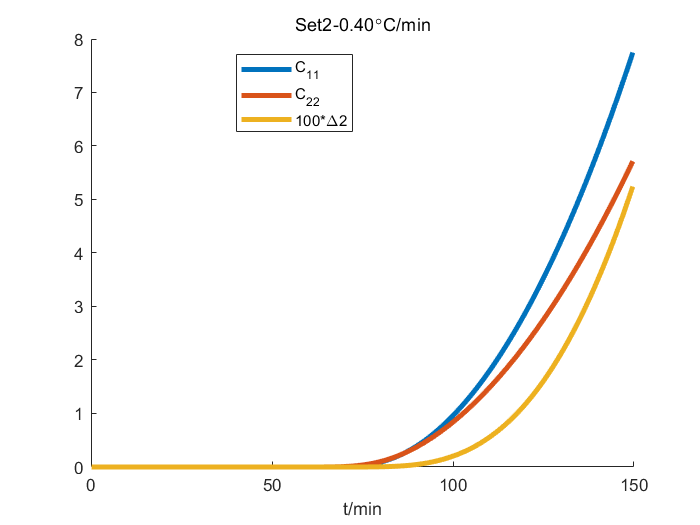

Set = Set2;
%set up times and parameter estimations
t=min(x2):0.1:max(x2);%time
t=t';%make t a column
m=length(t);

beta(1)=AsymD;
beta(2)=z;
p = length(beta);

%% Compute C11, C12,...delta for opt exptl design
fname=@MicroInactFOR;
Xp=SSC_V4(beta,t,fname,Set);%compute scaled sensitivity coefficients as a cell array

%compute entire C matrix
for i=1:p 
    for j=1:p
        intgrnd=Xp{i}.*Xp{j};
        C{i,j}=(1./t).*cumtrapz(t,intgrnd);
        clear intgrnd
    end
end
%to compute delta, must set up the C matrix for each time
for i=1:p
    for j=1:p
        CC2(i,j,:)=C{i,j}; %gives a 3D matrix that is m (depth) in time
    end
end

%set all CC(:,:,1) (first page) values to the appropriate number
CC2(:,:,1)=0;%beginning values at time = 0
CC2(1,1,1)=0;%except for C11, for the initial value
delta2(1)=0; %determinant at time zero.
for k=2:m
    delta2(k)=det(CC2(:,:,k));
end

%convert 3D to 2D for plotting
i=1;
d=1;
%for first row, i =1
for j=1:p
    Cp2(d,:)=CC2(i,j,:); %copies the Cij values for all times and stores in Cp(d,:)
    d=d+1;
end
%for second row, i=2; Cp(3) holds C21
i=2;
for j=2:p
    Cp2(d,:)=CC2(i,j,:);
    d=d+1;
end


figure
hold on
fac=32;%factor for plotting
f=1;%factor
h(1)=plot(t,Cp2(1,:),'-','linewidth',3);%C11
h(2)=plot(t,f*Cp2(3,:),'-','linewidth',3);%C22
h(3)=plot(t,100*f*delta2,'-','linewidth',3);
%set(gca,'YTick',0:.2:1.6)
%set(gca, 'fontsize',28,'fontweight','bold');
xlabel('t/min')
title('Set2-0.40{\circ}C/min');
legend('C_{11}','C_{22}','100*\Delta2','Location','Best')

#### 5.3 Optimal experimental design for Data Set3 - 1.64

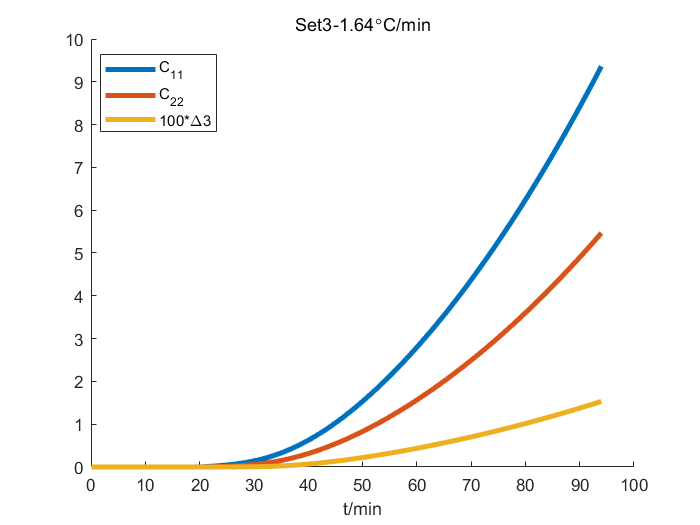

Set = Set3;
%set up times and parameter estimations
t=min(x3):0.1:max(x3);%time
t=t';%make t a column
m=length(t);

beta(1)=AsymD;
beta(2)=z;
p = length(beta);

%% Compute C11, C12,...delta for opt exptl design
fname=@MicroInactFOR;
Xp=SSC_V4(beta,t,fname,Set);%compute scaled sensitivity coefficients as a cell array

%compute entire C matrix
for i=1:p 
    for j=1:p
        intgrnd=Xp{i}.*Xp{j};
        C{i,j}=(1./t).*cumtrapz(t,intgrnd);
        clear intgrnd
    end
end
%to compute delta, must set up the C matrix for each time
for i=1:p
    for j=1:p
        CC3(i,j,:)=C{i,j}; %gives a 3D matrix that is m (depth) in time
    end
end

%set all CC(:,:,1) (first page) values to the appropriate number
CC3(:,:,1)=0;%beginning values at time = 0
CC3(1,1,1)=0;%except for C11, for the initial value
delta3(1)=0; %determinant at time zero.
for k=2:m
    delta3(k)=det(CC3(:,:,k));
end

%convert 3D to 2D for plotting
i=1;
d=1;
%for first row, i =1
for j=1:p
    Cp3(d,:)=CC3(i,j,:); %copies the Cij values for all times and stores in Cp(d,:)
    d=d+1;
end
%for second row, i=2; Cp(3) holds C21
i=2;
for j=2:p
    Cp3(d,:)=CC3(i,j,:);
    d=d+1;
end


figure
hold on
fac=32;%factor for plotting
f=1;%factor
h(1)=plot(t,Cp3(1,:),'-','linewidth',3);%C11
h(2)=plot(t,f*Cp3(3,:),'-','linewidth',3);%C22
h(3)=plot(t,100*f*delta3,'-','linewidth',3);
%set(gca,'YTick',0:.2:1.6)
%set(gca, 'fontsize',28,'fontweight','bold');
xlabel('t/min')
title('Set3-1.64{\circ}C/min');
legend('C_{11}','C_{22}','100*\Delta3','Location','Best')

## 6. **Bootstrapping**

nlinfitcheck = statset('nlinfit');
nlinfitcheck.FunValCheck='off';

t=xobs;
n=length(t);
p=length(beta);

beta0(1)   = 5.67;
beta0(2)   = 4.11;

nboot=1000;
betab(1,:)=beta;%put beta from original data as first row
ypredb(1,:)=ypred;%put Cpred from original data as first row
rr(1,:) = resids;
% mm=1;%use x1, y1; x2, y2;... bootstrapping the data
 mm=2;%use x1, Ypred1+e1; x2, Ypred2+e2;... bootstrapping the residuals
for j=2:nboot
    r=round(1 + (n-1).*rand(n,1));%index of random integers from 1 to n
    clear yboot
    for i=1:n
       if mm==1
           tt(i)=t(r(i));%tt(i) is the time for each bootstrapped datum
           yboot(i)=yobs(r(i));%yboot(i) is the y value for each bootstrapped datum
           if i==n
               yboot=yboot'; %make yboot a column
           end
       end

       if mm==2
           tt=t;
           yboot(i)=ypred(i)+resids(r(i));
           if i==n
               yboot=yboot'; %make yboot a column 
           end 
       end
       
    end
    
    yboot;
    [betab(j,:),rr(j,:),J2,COVB2,mse2]= nlinfit(tt,yboot,fnameINV,beta0,nlinfitcheck);%betab are the parameters from the bootstrapping
    ypredb(j,1:nS(1))=fnameFOR(betab(j,:),t(1:nS(1)), Set1);%should change "t" to tpred(1000,1) using linspace
    ypredb(j,nS(1)+1:nS(2))=fnameFOR(betab(j,:),t(nS(1)+1:nS(2)), Set2);%should change "t" to tpred(1000,1) using linspace
    ypredb(j,nS(2)+1:nS(3))=fnameFOR(betab(j,:),t(nS(2)+1:nS(3)), Set3);%should change "t" to tpred(1000,1) using linspace
    clear yboot
end
r2=rr(1,:)';%save the residuals from first bootstrapping
%r2=resids;
for j=2:nboot
    r2=[r2; rr(j,:)']; %build a matrix "r2" where each column holds residuals for one bootstrap
end
bsort=sort(betab,1); ysort=sort(ypredb,1); %"1" means sorts along columns
L=round(0.025*nboot); %L is lower 2.5% cutoff
if L==0;  L=1;  end %if L = 0, switch to L = 1 to avoid MATLAB error
U=round(0.975*nboot); %U is upper 2.5% cutoff
cib(1,1)=bsort(L,1); cib(1,2)=bsort(U,1);%bootstrap 95% CI for first beta
cib(2,1)=bsort(L,2); cib(2,2)=bsort(U,2);%bootstrap 95% CI for second beta
for i=1:n
    ybci(i,1)=ysort(L,i); ybci(i,2)=ysort(U,i);%ybci is a n-by-2 matrix with bootstrap CI for y at each time
end

D=rmse*tinv(.975,n-p);
CIwb(:,1)=ybci(:,2)-ypred; CIwb(:,2)=ypred-ybci(:,1); %upper (column 1) and lower (column 2) bootstrap CIwidths
PIwb(:,1)=sqrt(CIwb(:,1).^2+D^2); PIwb(:,2)=sqrt(CIwb(:,2).^2+D^2);%upper and lower widths of PI
PIb(:,1)=ypred+PIwb(:,1); PIb(:,2)=ypred-PIwb(:,2); %PI values

### 6. **Bootstrapping**

### 6.1 Set1-0.15

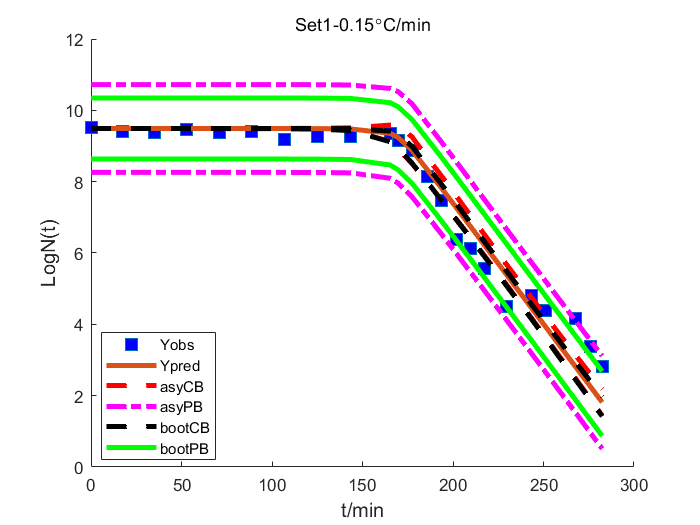

figure
hold on
clear h1
fac3=3; %line width
%set(gca, 'fontsize',32,'fontweight','bold');
L4 = ['t/min'];
xlabel(L4,'fontsize',12);
% ylabel('log{\itS}_a','fontsize',16,'fontweight','bold');
ylabel('LogN(t)','fontsize',12);
title('Set1-0.15{\circ}C/min');
h1(1)=plot(t(1:nS(1)),yobs(1:nS(1)),'square', 'Markerfacecolor', 'b','markersize',9);
h1(2) = plot(t(1:nS(1)),ypred(1:nS(1)),'-','LineWidth',fac3);
legend(h1,'Yobs','Ypred','location','best')
h1(3) = plot(t(1:nS(1)),CBu(1:nS(1)),'--r','LineWidth',fac3);
plot(t(1:nS(1)),CBl(1:nS(1)),'--r','LineWidth',fac3);
legend(h1,'Yobs','Ypred','asyCB','location','best')

h1(4) = plot(t(1:nS(1)),PBu(1:nS(1)),'-.m','LineWidth',fac3);
plot(t(1:nS(1)),PBl(1:nS(1)),'-.m','LineWidth',fac3);
legend(h1,'Yobs','Ypred','asyCB','asyPB','location','best')
ybci11 = ybci(:,1);
ybci12 = ybci(:,2);
h1(5) = plot(t(1:nS(1)),ybci11(1:nS(1)),'--k','LineWidth',fac3);
plot(t(1:nS(1)),ybci12(1:nS(1)),'--k','LineWidth',fac3);
legend(h1,'Yobs','Ypred','asyCB','asyPB','bootCB','location','best')


PIb11 = PIb(:,1);
PIb12 = PIb(:,2);
h1(6) = plot(t(1:nS(1)),PIb11(1:nS(1)),'-g','LineWidth',fac3);
plot(t(1:nS(1)),PIb12(1:nS(1)),'-g','LineWidth',fac3);
legend(h1,'Yobs','Ypred','asyCB','asyPB','bootCB','bootPB','location','best')
hold off

### 6. **Bootstrapping**

### 6.2 Set2-0.40

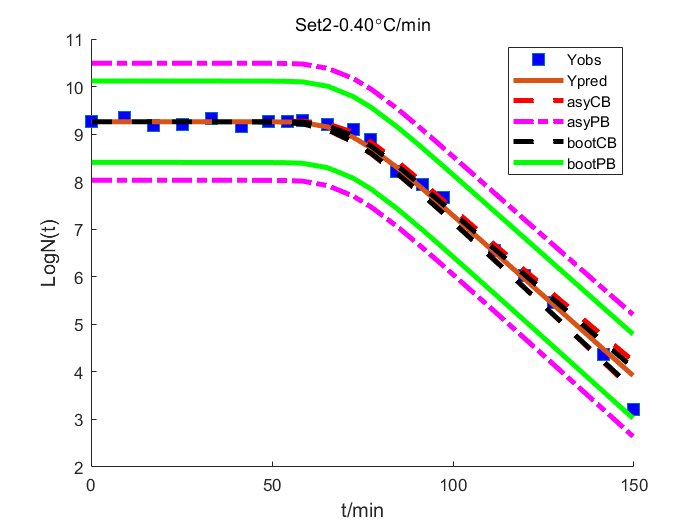

figure
hold on
clear h1
fac3=3; %line width
%set(gca, 'fontsize',32,'fontweight','bold');
L4 = ['t/min'];
xlabel(L4,'fontsize',12);
% ylabel('log{\itS}_a','fontsize',16,'fontweight','bold');
ylabel('LogN(t)','fontsize',12);
title('Set2-0.40{\circ}C/min');
h1(1)=plot((t(nS(1)+1:nS(2))),yobs(nS(1)+1:nS(2)),'square', 'Markerfacecolor', 'b','markersize',9);
h1(2) = plot(t(nS(1)+1:nS(2)),ypred(nS(1)+1:nS(2)),'-','LineWidth',fac3);
legend(h1,'Yobs','Ypred','location','best')
h1(3) = plot(t(nS(1)+1:nS(2)),CBu(nS(1)+1:nS(2)),'--r','LineWidth',fac3);
plot(t(nS(1)+1:nS(2)),CBl(nS(1)+1:nS(2)),'--r','LineWidth',fac3);
legend(h1,'Yobs','Ypred','asyCB','location','best')

h1(4) = plot(t(nS(1)+1:nS(2)),PBu(nS(1)+1:nS(2)),'-.m','LineWidth',fac3);
plot(t(nS(1)+1:nS(2)),PBl(nS(1)+1:nS(2)),'-.m','LineWidth',fac3);
legend(h1,'Yobs','Ypred','asyCB','asyPB','location','best')
ybci21 = ybci(:,1);
ybci22 = ybci(:,2);
h1(5) = plot(t(nS(1)+1:nS(2)),ybci21(nS(1)+1:nS(2)),'--k','LineWidth',fac3);
plot(t(nS(1)+1:nS(2)),ybci22(nS(1)+1:nS(2)),'--k','LineWidth',fac3);
legend(h1,'Yobs','Ypred','asyCB','asyPB','bootCB','location','best')


PIb21 = PIb(:,1);
PIb22 = PIb(:,2);
h1(6) = plot(t(nS(1)+1:nS(2)),PIb21(nS(1)+1:nS(2)),'-g','LineWidth',fac3);
plot(t(nS(1)+1:nS(2)),PIb22(nS(1)+1:nS(2)),'-g','LineWidth',fac3);
legend(h1,'Yobs','Ypred','asyCB','asyPB','bootCB','bootPB','location','best')
hold off

### 6. **Bootstrapping**

### 6.3 Set3-1.64

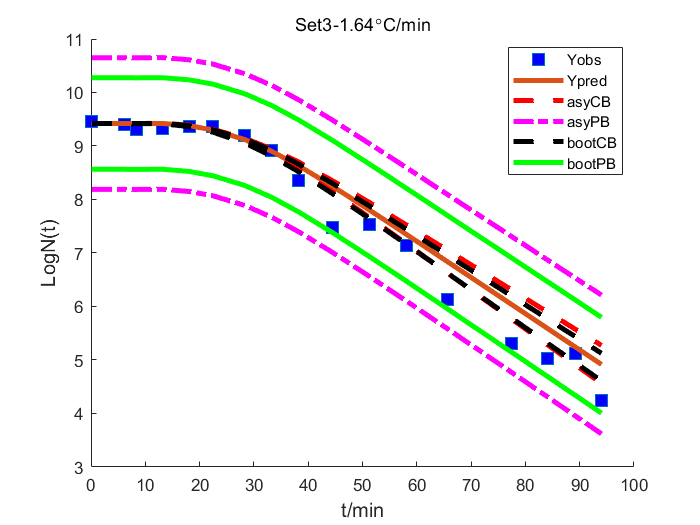

figure
hold on
clear h1
fac3=3; %line width
%set(gca, 'fontsize',32,'fontweight','bold');
L4 = ['t/min'];
xlabel(L4,'fontsize',12);
% ylabel('log{\itS}_a','fontsize',16,'fontweight','bold');
ylabel('LogN(t)','fontsize',12);
title('Set3-1.64{\circ}C/min');
h1(1)=plot((t(nS(2)+1:nS(3))),yobs(nS(2)+1:nS(3)),'square', 'Markerfacecolor', 'b','markersize',9);
h1(2) = plot(t(nS(2)+1:nS(3)),ypred(nS(2)+1:nS(3)),'-','LineWidth',fac3);
legend(h1,'Yobs','Ypred','location','best')
h1(3) = plot(t(nS(2)+1:nS(3)),CBu(nS(2)+1:nS(3)),'--r','LineWidth',fac3);
plot(t(nS(2)+1:nS(3)),CBl(nS(2)+1:nS(3)),'--r','LineWidth',fac3);
legend(h1,'Yobs','Ypred','asyCB','location','best')

h1(4) = plot(t(nS(2)+1:nS(3)),PBu(nS(2)+1:nS(3)),'-.m','LineWidth',fac3);
plot(t(nS(2)+1:nS(3)),PBl(nS(2)+1:nS(3)),'-.m','LineWidth',fac3);
legend(h1,'Yobs','Ypred','asyCB','asyPB','location','best')
ybci31 = ybci(:,1);
ybci32 = ybci(:,2);
h1(5) = plot(t(nS(2)+1:nS(3)),ybci31(nS(2)+1:nS(3)),'--k','LineWidth',fac3);
plot(t(nS(2)+1:nS(3)),ybci32(nS(2)+1:nS(3)),'--k','LineWidth',fac3);
legend(h1,'Yobs','Ypred','asyCB','asyPB','bootCB','location','best')


PIb31 = PIb(:,1);
PIb32 = PIb(:,2);
h1(6) = plot(t(nS(2)+1:nS(3)),PIb31(nS(2)+1:nS(3)),'-g','LineWidth',fac3);
plot(t(nS(2)+1:nS(3)),PIb32(nS(2)+1:nS(3)),'-g','LineWidth',fac3);
legend(h1,'Yobs','Ypred','asyCB','asyPB','bootCB','bootPB','location','best')
hold off

## 0. Functions Used

%% functions

function y=MicroInactFOR(beta,t,Set) %call the FOR function each time you wish to plot ypred for a data set
    
    logCc0     =0.82;
    ln10    = 2.3026;
    Tref    = 56.3;
    Tdiff   = 25;
    T0      = 30;
    B       = 5*10^-4;
    Y0      = [9.49; 9.26; 9.42];
    Tcrit   = [168.27; 61.98; 15.27];
    
    y0    = Y0(Set);
    tcrit = Tcrit(Set);
    tspan = unique(t);
    
    [t,y]=ode45(@ff,tspan,[y0, logCc0]); %data set 1 ypred
        
        function dy=ff(t,y)
            
            T     = T0 + Tdiff * (  ( (t+tcrit) - sqrt( (t+tcrit)^2 - 4*(tcrit-B)*t ) ) / ( 2*(tcrit-B) )  );
            kmax  = (ln10/beta(1)) * exp( ln10/beta(2) * (T - Tref) );
            k     = kmax * (1/( 1+10^y(2) ));
            dy(1) = -(1/ln10) * k;
            dy(2) = -(1/ln10) * kmax;
            dy    = dy';
            
        end
       
     y1=y(:,1);y2=y(:,2);
     y=y1;
 end


% Inverse Problem
function y = MicroInactINV(beta,t)

    logCc0     =0.82;
    ln10    = 2.3026;
    Tref    = 56.3;
    Tdiff   = 25;
    T0      = 30;
    B       = 5*10^-4;
    Y0      = [9.49; 9.26; 9.42];
    Tcrit   = [168.27; 61.98; 15.27];
    
    y01    = Y0(1);
    tcrit1 = Tcrit(1);
    y02    = Y0(2);
    tcrit2 = Tcrit(2);
    y03    = Y0(3);
    tcrit3 = Tcrit(3);

    global nS
    tspan1 = unique( t(1:nS(1)) );
    tspan2 = unique( t(nS(1)+1:nS(2)) );
    tspan3 = unique( t(nS(2)+1:nS(3)) );

    [t1,y1]=ode45(@ff1,tspan1,[y01, logCc0]); %data set 1 ypred
    [t2,y2]=ode45(@ff2,tspan2,[y02, logCc0]); %data set 2 ypred
    [t3,y3]=ode45(@ff3,tspan3,[y03, logCc0]); %data set 3 ypred
    
    y11 = y1(:,1);
    y21 = y2(:,1);
    y31 = y3(:,1);
    y  = [y11; y21; y31];
    
    %data set1
    function dy=ff1(t,y)
            
            T     = T0 + Tdiff * (  ( (t+tcrit1) - sqrt( (t+tcrit1)^2 - 4*(tcrit1-B)*t ) ) / ( 2*(tcrit1-B) )  );
            kmax  = (ln10/beta(1)) * exp( ln10/beta(2) * (T - Tref) );
            k     = kmax * (1/( 1+10^y(2) ));
            dy(1) = -(1/ln10) * k;
            dy(2) = -(1/ln10) * kmax;
            dy    = dy';
            
    end
    
    
    %data set2
    function dy=ff2(t,y)
            
            T     = T0 + Tdiff * (  ( (t+tcrit2) - sqrt( (t+tcrit2)^2 - 4*(tcrit2-B)*t ) ) / ( 2*(tcrit2-B) )  );
            kmax  = (ln10/beta(1)) * exp( ln10/beta(2) * (T - Tref) );
            k     = kmax * (1/( 1+10^y(2) ));
            dy(1) = -(1/ln10) * k;
            dy(2) = -(1/ln10) * kmax;
            dy    = dy';
            
    end
    
    %data set3
    function dy=ff3(t,y)
            
            T     = T0 + Tdiff * (  ( (t+tcrit3) - sqrt( (t+tcrit3)^2 - 4*(tcrit3-B)*t ) ) / ( 2*(tcrit3-B) )  );
            kmax  = (ln10/beta(1)) * exp( ln10/beta(2) * (T - Tref) );
            k     = kmax * (1/( 1+10^y(2) ));
            dy(1) = -(1/ln10) * k;
            dy(2) = -(1/ln10) * kmax;
            dy    = dy';
            
    end
    

end

function Xp=SSC_V3(beta,x,yfunc,Set)

    d=0.001;
    ypred=yfunc(beta,x,Set);

    for i = 1:length(beta)  %scaled sens coeff for forward problem
        betain = beta; %reset beta
        betain(i) = beta(i)*(1+d);
        yhat{i} = yfunc(betain,x,Set);
        SSC{i} = (yhat{i}-ypred)/d;%scaled sens coeff for ith parameter
        Xp(:,i)=SSC{i}; %extract from cell array to 2D array
    end

end

function Xp=SSC_V4(beta,x,yfunc,Set)
    d=0.001;
    ypred=yfunc(beta,x,Set);
    for i = 1:length(beta)  %scaled sens coeff for forward problem
        betain = beta; %reset beta
        betain(i) = beta(i)*(1+d);
        yhat{i} = yfunc(betain,x,Set);
        Xp{i} = (yhat{i}-ypred)/d;%scaled sens coeff for ith parameter
    end
end
